# Deploy Simple Pose Estimation on NVIDIA® Jetson™ Using GPU Coder™

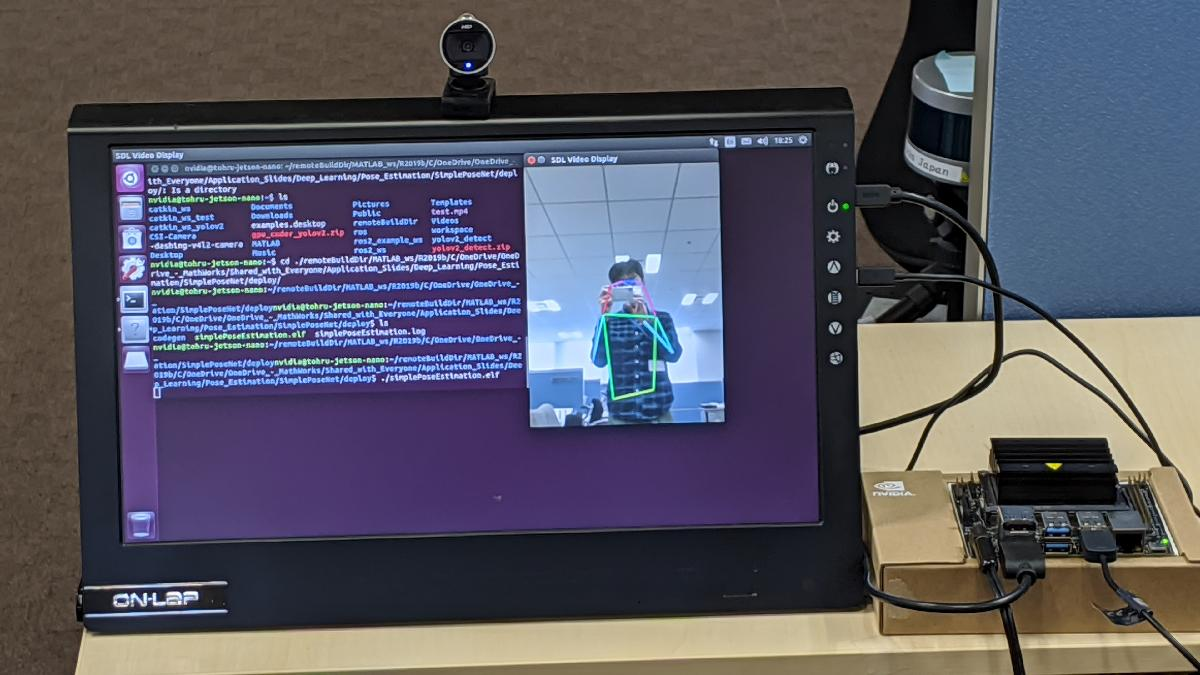

Running on a Jetson Nano.

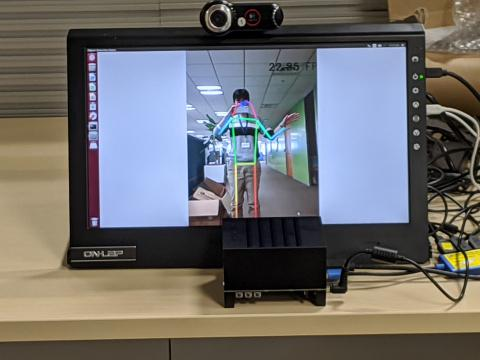

Running on a Jetson AGX Xavier.

## **System Requirements**

[https://www.mathworks.com/help/supportpkg/nvidia/ug/install-and-setup-prerequisites.html](https://www.mathworks.com/help/supportpkg/nvidia/ug/install-and-setup-prerequisites.html)

## **Connect to the NVIDIA Hardware**

clear;
hwobj = jetson('tohru-jetson-nano', 'nvidia', 'nvidia');

## **Verify the GPU Environment**

Use the [coder.checkGpuInstall](matlab:doc('coder.checkGpuInstall')) function and verify that the compilers and libraries needed for running this example are set up correctly.

envCfg = coder.gpuEnvConfig('jetson');
envCfg.DeepLibTarget = 'cudnn';
envCfg.DeepCodegen = 1;
envCfg.HardwareObject = hwobj;
coder.checkGpuInstall(envCfg);

## **Prepare Pose Estimation for Stand-Alone Deployment**

Include the webcam and display interfaces inside the Sobel edge detection application

w = webcam(hwobj);
img = snapshot(w);
d = imageDisplay(hwobj);
image(d,img);

## Test Pose Estimation Function on MATLAB

clear hwobj d w envCfg;
figure;
set(gcf,'Visible','on');
simplePoseEstimation
% Need to Ctrl+C to stop the running program.

## **Generate CUDA Code for the Target Using GPU Coder**

cfg = coder.gpuConfig('exe');
cfg.Hardware = coder.hardware('NVIDIA Jetson');
cfg.Hardware.BuildDir = '~/remoteBuildDir';
cfg.DeepLearningConfig = coder.DeepLearningConfig('cudnn');
cfg.GenerateExampleMain = 'GenerateCodeAndCompile';
codegen('-config ',cfg,'simplePoseEstimation.m','-report');

## Run the Pose Estimation on the Target

To run the generated executable on the target, use the MATLAB® runApplication function.

clear hwobj;
hwobj = jetson
pid = runApplication(hwobj,'simplePoseEstimation');

%killApplication(hwobj,'simplePoseEstimation');

## Next Step

- Try to deploy [`multiPersonPoseEstimation`](matlab:open('./multiPersonPoseEstimation.m')) as well.

*Copyright 2020-2023 The MathWorks, Inc.*